% Policy 2: Optimal Dispatch & Visualisations
% Formulates the LP and compares it against Policy 1

% LP Formulation
% Assumes P_total_load, P_pv, tariffs, and params are already in the workspace from Script 1
prob = optimproblem('ObjectiveSense', 'minimize');

% Decision Variables (T steps)
P_ch = optimvar('P_ch', N, 1, 'LowerBound', 0, 'UpperBound', P_max);
P_dis = optimvar('P_dis', N, 1, 'LowerBound', 0, 'UpperBound', P_max);
P_imp = optimvar('P_imp', N, 1, 'LowerBound', 0);
P_exp = optimvar('P_exp', N, 1, 'LowerBound', 0);
S_use = optimvar('S_use', N, 1, 'LowerBound', 0); % PV directly used

% State Variable (T+1 steps)
SOC_opt = optimvar('SOC_opt', N+1, 1, 'LowerBound', 0, 'UpperBound', cap_kWh);

% Objective: Minimise Net Cost
prob.Objective = sum((P_imp .* tariff_imp - P_exp .* tariff_exp) * dt);

% Constraints
prob.Constraints.pv_limit = S_use + P_ch + P_exp <= P_pv; 
prob.Constraints.energy_balance = S_use + P_dis + P_imp == P_total_load + P_ch + P_exp;
prob.Constraints.soc_init = SOC_opt(1) == soc_init;
prob.Constraints.soc_dyn = SOC_opt(2:end) == SOC_opt(1:end-1) + (P_ch * eta_ch - P_dis / eta_dis) * dt;
prob.Constraints.soc_end = SOC_opt(end) >= soc_init; 

% Solve LP
options = optimoptions('linprog', 'Display', 'none');
[sol, total_cost_opt, exitflag, output] = solve(prob, 'Options', options);

% Verification
fprintf('\n--- POLICY 2 (OPTIMAL) VERIFICATION ---\n');


--- POLICY 2 (OPTIMAL) VERIFICATION ---


if exitflag == 1
    fprintf('PASS: Solver status is Optimal.\n');
else
    fprintf('FAIL: Solver failed to find optimal solution.\n');
end

PASS: Solver status is Optimal.



balance_residual = sol.S_use + sol.P_dis + sol.P_imp - P_total_load - sol.P_ch - sol.P_exp;
if max(abs(balance_residual)) < 1e-6
    fprintf('PASS: Energy balance residuals are < 1e-6.\n');
else
    fprintf('FAIL: Energy balance violated.\n');
end

PASS: Energy balance residuals are < 1e-6.



if all(sol.SOC_opt >= -1e-6) && all(sol.SOC_opt <= cap_kWh + 1e-6)
    fprintf('PASS: SOC bounds respected.\n');
else
    fprintf('FAIL: SOC limits violated.\n');
end

PASS: SOC bounds respected.



fprintf('Policy 2 Net Cost: £%.2f\n', total_cost_opt);

Policy 2 Net Cost: £195.42


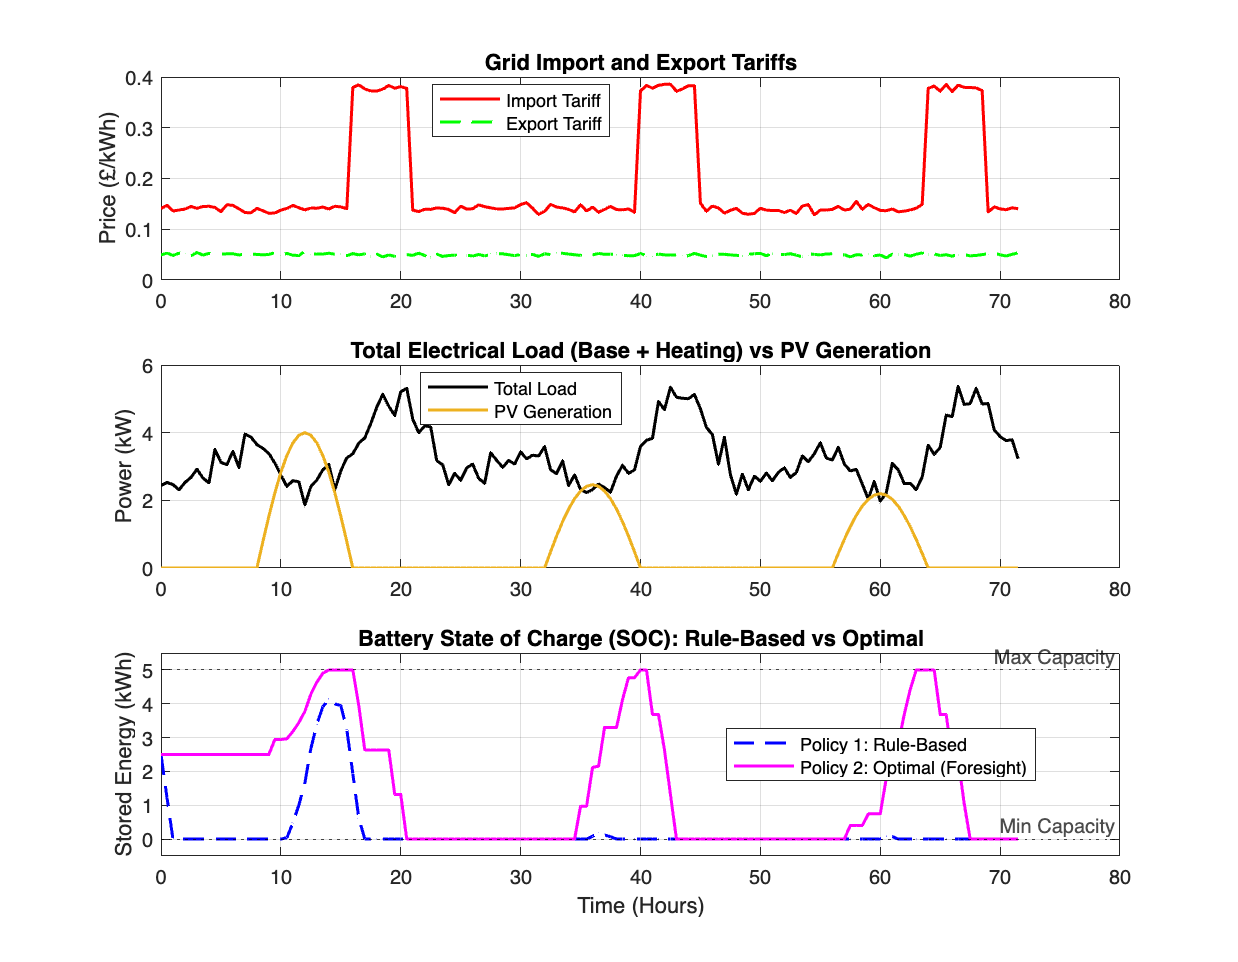


% Plotting a 3-day window to see the behaviour clearly
time_window = 1:144;
hours = (0:length(time_window)-1) * 0.5;

figure('Name', 'Policy Comparison: Rule-Based vs Optimal', 'Position', [100, 100, 900, 700]);

% Plot 1: Tariffs
subplot(3,1,1);
plot(hours, tariff_imp(time_window), 'r-', 'LineWidth', 1.5); hold on;
plot(hours, tariff_exp(time_window), 'g--', 'LineWidth', 1.5);
title('Grid Import and Export Tariffs');
ylabel('Price (£/kWh)');
legend('Import Tariff', 'Export Tariff', 'Location', 'best');
grid on;

% Plot 2: Load vs PV
subplot(3,1,2);
plot(hours, P_total_load(time_window), 'k-', 'LineWidth', 1.5); hold on;
plot(hours, P_pv(time_window), 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 1.5);
title('Total Electrical Load (Base + Heating) vs PV Generation');
ylabel('Power (kW)');
legend('Total Load', 'PV Generation', 'Location', 'best');
grid on;

% Plot 3: SOC Comparison
subplot(3,1,3);
plot(hours, SOC_rule(time_window), 'b--', 'LineWidth', 1.5); hold on;
plot(hours, sol.SOC_opt(time_window), 'm-', 'LineWidth', 1.5);
yline(cap_kWh, 'k:', 'Max Capacity'); 
yline(0, 'k:', 'Min Capacity'); 
title('Battery State of Charge (SOC): Rule-Based vs Optimal');
xlabel('Time (Hours)');
ylabel('Stored Energy (kWh)');
legend('Policy 1: Rule-Based', 'Policy 2: Optimal (Foresight)', 'Location', 'best');
ylim([-0.5, cap_kWh + 0.5]);
grid on;

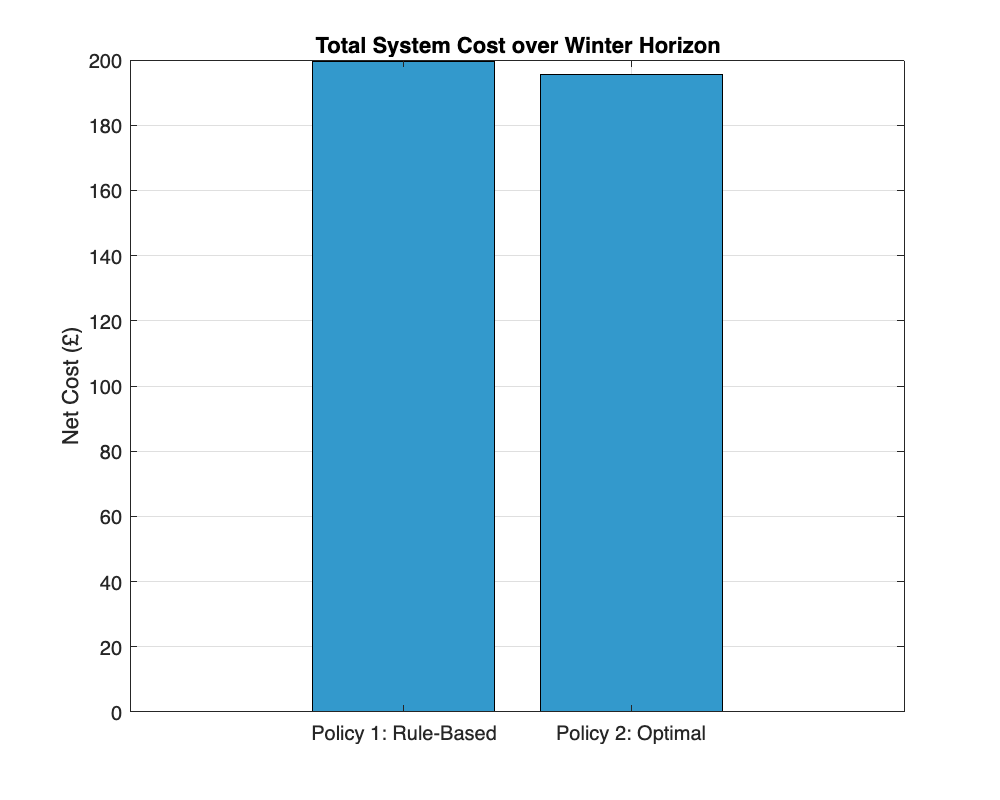


% Figure 2: Economic Summary
figure('Name', 'Economic Comparison', 'Position', [200, 200, 500, 400]);
costs = [total_cost_rule, total_cost_opt]; 
bar(costs, 'FaceColor', [0.2 0.6 0.8]);
set(gca, 'XTickLabel', {'Policy 1: Rule-Based', 'Policy 2: Optimal'});
title('Total System Cost over Winter Horizon');
ylabel('Net Cost (£)');
grid on;